# 20.320 Project 2

MATLAB code to produce plots and figures.

## Non-Quarantine Model

## Parameters

Here are all our parameters with units specified in the comments.

options = odeset('AbsTol', 1e-12, 'RelTol', 1e-12);
y0 = [1E-10, 5E5, 0, 0, 0, 0, 0, 2E-6, 0]; % Initial conditions
k = [Kf, Kr, Vs, Ker, Krec_r, Kdeg_r, Kdeg_d...
Ked, Kcat, Kf_d, Kr_d, Kf_g, Kr_g]';

tspan = logspace(0, 10);
[t,y] = ode15s(@StandardSystem, tspan, y0, options, k);

close all
loglog(t, y, 'LineWidth', 3);
title('Concentration vs. Time');
xlabel('Time [s]');
ylabel('Concentration [M?]');
lgd = legend('L', 'Rs', 'Cs', 'Ri', 'Ds', 'PDs', 'PDi', 'Grb2', 'PDs_{Grb2}');
lgd.FontSize = 18;

## Quarantine Model 

## Parameters

Vb = 

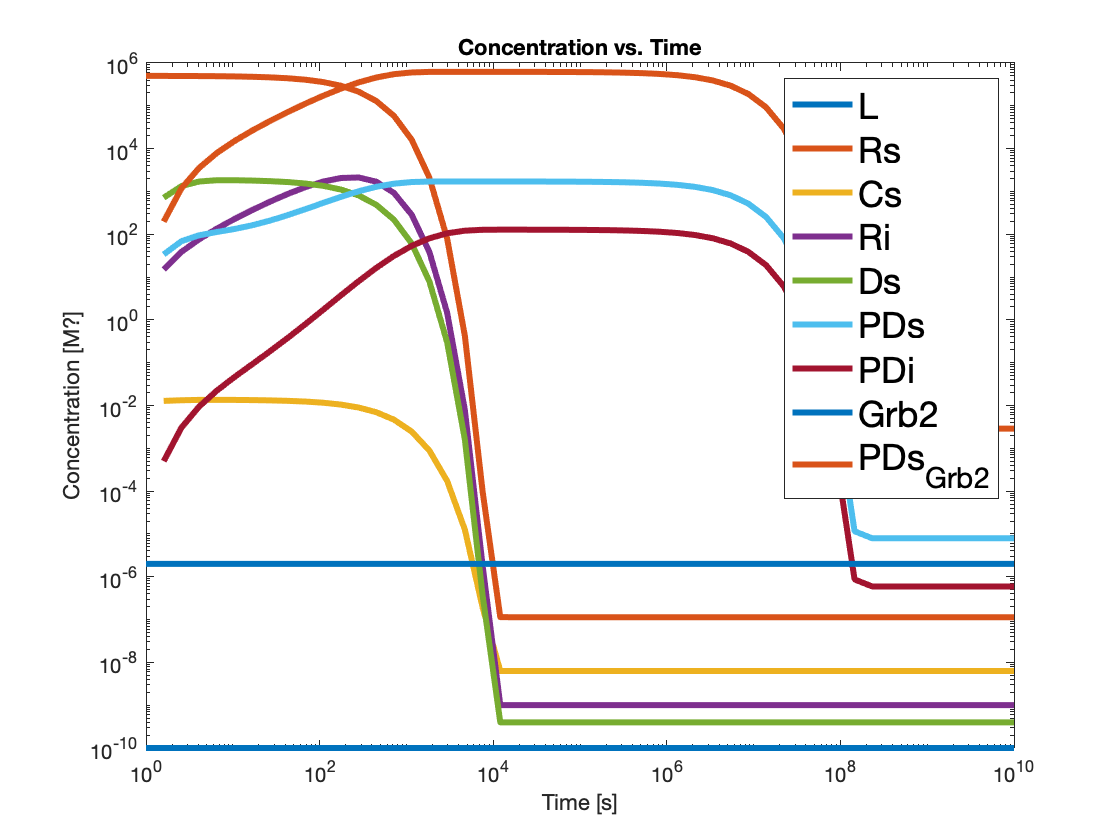

options = odeset('AbsTol', 1e-12, 'RelTol', 1e-12);
y_ab = [1E-8,2E-6, 5E5/(6.022E23)/(4/3*3.14*(15E-6)^3), 0, 0, 0, 0,0]; % Initial conditions

k = [Vs, Kf_d,Kr_d,Kf_g,Kr_g,Kemr,Krec_mR,Kcat,Kerg,Krec_rg,Kdeg_erg,Kdeg_mR]';

tspan = logspace(0, 10);
[t,y] = ode15s(@AberrantSystem, tspan, y_ab, options, k);

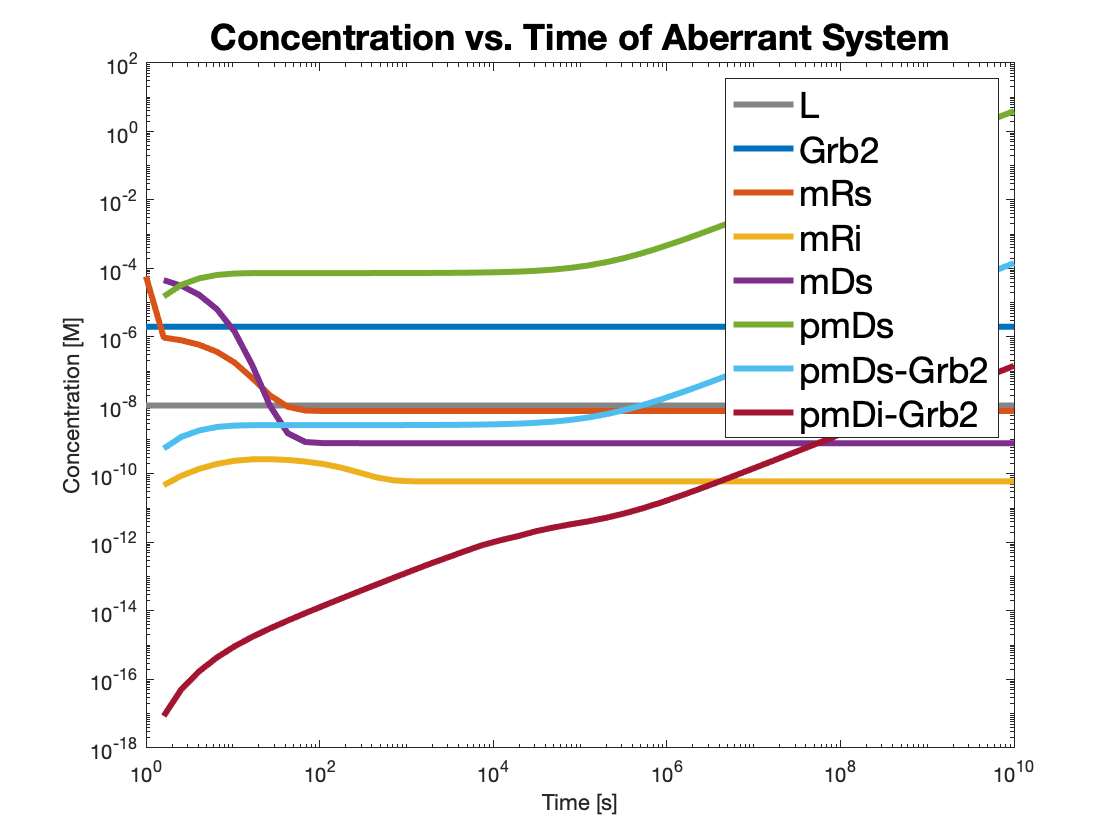

close all
loglog(t, y(:, 1), 'LineWidth', 3, 'Color', '#858585');
hold on
loglog(t, y(:, 2),'LineWidth', 3, 'Color', '[0, 0.4470, 0.7410]');
loglog(t, y(:, 3),'LineWidth', 3, 'Color', '[0.8500, 0.3250, 0.0980]');
loglog(t, y(:, 4),'LineWidth', 3, 'Color', '[0.9290, 0.6940, 0.1250]');
loglog(t, y(:, 5),'LineWidth', 3, 'Color', '[0.4940, 0.1840, 0.5560]');
loglog(t, y(:, 6),'LineWidth', 3, 'Color', '[0.4660, 0.6740, 0.1880]');
loglog(t, y(:, 7),'LineWidth', 3, 'Color', '[0.3010, 0.7450, 0.9330]');
loglog(t, y(:, 8),'LineWidth', 3, 'Color', '[0.6350, 0.0780, 0.1840]');

tt = title('Concentration vs. Time of Aberrant System');
xlabel('Time [s]');
ylabel('Concentration [M]');
lgd = legend('L','Grb2','mRs','mRi','mDs','pmDs','pmDs-Grb2','pmDi-Grb2');
lgd.FontSize = 18;
tt.FontSize = 18;